# #1

## step zero

clear
close all

## Param

Rint = 0.03;
h = 20;
k = 1.4;

Rstep = 0.005;
Rmin=0.04;
Rmax=0.08;
Lstep = 1;
Lmin=10;
Lmax=40;

## Decision variable

% it means the variable
% in this case it's rayon r and length l
R=Rmin:Rstep:Rmax;
L=Lmin:Lstep:Lmax;
disp(["Length of vector R: ",length(R)])

    "Length of vector R: "    "9"



disp(["Length of vector L: ",length(L)])

    "Length of vector L: "    "31"



## Objective function

% The function, the physical equation
Rth=1./(2*pi*h.*R.*L')+log(R./Rint)./(2*pi*k.*L') %résistance thermique

Rth =     0.0232    0.0223    0.0217    0.0214    0.0211    0.0210    0.0210    0.0210    0.0211
    0.0211    0.0203    0.0197    0.0194    0.0192    0.0191    0.0191    0.0191    0.0192
    0.0193    0.0186    0.0181    0.0178    0.0176    0.0175    0.0175    0.0175    0.0176
    0.0178    0.0171    0.0167    0.0164    0.0163    0.0162    0.0162    0.0162    0.0162
    0.0165    0.0159    0.0155    0.0153    0.0151    0.0150    0.0150    0.0150    0.0151
    0.0154    0.0149    0.0145    0.0142    0.0141    0.0140    0.0140    0.0140    0.0141
    0.0145    0.0139    0.0136    0.0133    0.0132    0.0131    0.0131    0.0131    0.0132
    0.0136    0.0131    0.0128    0.0126    0.0124    0.0124    0.0124    0.0124    0.0124
    0.0129    0.0124    0.0121    0.0119    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0122    0.0117    0.0114    0.0112    0.0111    0.0111    0.0111    0.0111    0.0111


% R in horizontal, L' in vertical
% R gives column number
% L gives line number
V=pi*(R.^2-Rint^2).*L' % V for volume

V =     0.0220    0.0353    0.0503    0.0668    0.0848    0.1045    0.1257    0.1484    0.1728
    0.0242    0.0389    0.0553    0.0734    0.0933    0.1149    0.1382    0.1633    0.1901
    0.0264    0.0424    0.0603    0.0801    0.1018    0.1253    0.1508    0.1781    0.2073
    0.0286    0.0459    0.0653    0.0868    0.1103    0.1358    0.1634    0.1930    0.2246
    0.0308    0.0495    0.0704    0.0935    0.1188    0.1462    0.1759    0.2078    0.2419
    0.0330    0.0530    0.0754    0.1001    0.1272    0.1567    0.1885    0.2227    0.2592
    0.0352    0.0565    0.0804    0.1068    0.1357    0.1671    0.2011    0.2375    0.2765
    0.0374    0.0601    0.0855    0.1135    0.1442    0.1776    0.2136    0.2523    0.2937
    0.0396    0.0636    0.0905    0.1202    0.1527    0.1880    0.2262    0.2672    0.3110
    0.0418    0.0672    0.0955    0.1268    0.1612    0.1985    0.2388    0.2820    0.3283


## Q1

Optimal value for Rth, and R and L corresponded

disp(["The min of Rth is ", min(min(Rth))])

    "The min of Rth is "    "0.0052501"



[ilig icol]=find(Rth==min(min(Rth)))

ilig = 31

icol = 7

%ilig is for L
%icol is for R
disp(["value of R is ", R(icol)])

    "value of R is "    "0.07"



disp(["value of L is ", L(ilig)])

    "value of L is "    "40"



## Optimal value for V, and R L corresponded

disp(["The min of V is ", min(min(V))])

    "The min of V is "    "0.021991"



[ilig icol]=find(V==min(min(V)))

ilig = 1

icol = 1

%ilig is for L
%icol is for R
disp(["value of R is ", R(icol)])

    "value of R is "    "0.04"



disp(["value of L is ", L(ilig)])

    "value of L is "    "10"



## Decision varialbe space

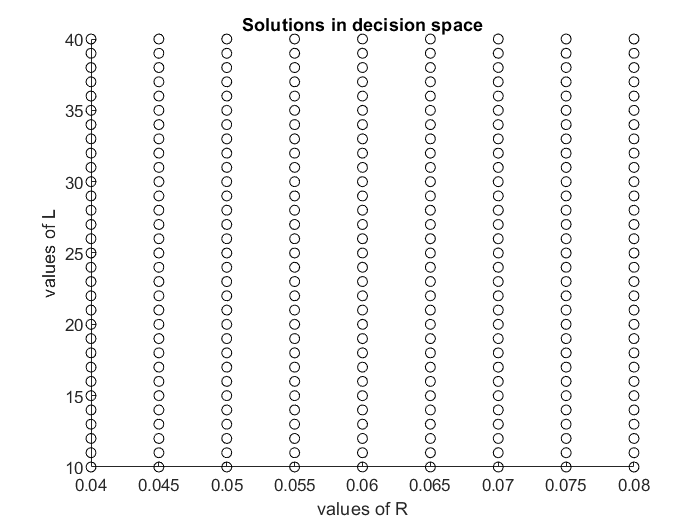

figure(1)
hold on
for i=1:length(L)
    for j=1:length(R)
        plot(R(j),L(i),'ko');
    end
end
title("Solutions in decision space")
xlabel("values of R")
ylabel("values of L")

## Objective space

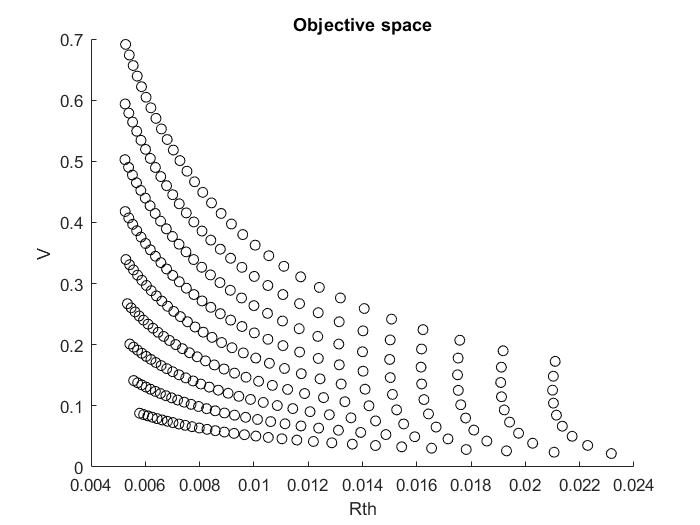

% plot combinaison de Rth et V, les 2 objective functions
figure(2)
hold on
plot(Rth,V,'ko')
title("Objective space")
xlabel("Rth")
ylabel("V")

% plot with two matrixs, is like plot vectors several times


## Pareto Set

% scale the objective functions
Rthscale=(Rth-min(min(Rth)))./(max(max(Rth))-min(min(Rth)))

Rthscale =     1.0000    0.9514    0.9195    0.8992    0.8871    0.8810    0.8792    0.8807    0.8846
    0.8824    0.8382    0.8093    0.7908    0.7798    0.7742    0.7726    0.7740    0.7775
    0.7845    0.7440    0.7174    0.7005    0.6904    0.6853    0.6838    0.6850    0.6883
    0.7016    0.6642    0.6397    0.6241    0.6148    0.6100    0.6087    0.6098    0.6128
    0.6306    0.5958    0.5731    0.5586    0.5499    0.5455    0.5443    0.5453    0.5481
    0.5690    0.5365    0.5153    0.5018    0.4937    0.4896    0.4884    0.4894    0.4920
    0.5151    0.4847    0.4648    0.4521    0.4446    0.4407    0.4396    0.4405    0.4430
    0.4676    0.4389    0.4202    0.4083    0.4012    0.3975    0.3965    0.3974    0.3997
    0.4253    0.3983    0.3806    0.3693    0.3626    0.3592    0.3582    0.3590    0.3612
    0.3875    0.3619    0.3451    0.3345    0.3281    0.3249    0.3239    0.3247    0.3268


Vscale=(V-min(min(V)))./(max(max(V))-min(min(V)))

Vscale =          0    0.0200    0.0423    0.0669    0.0939    0.1232    0.1549    0.1890    0.2254
    0.0033    0.0252    0.0498    0.0769    0.1066    0.1388    0.1737    0.2112    0.2512
    0.0066    0.0305    0.0573    0.0869    0.1192    0.1545    0.1925    0.2333    0.2770
    0.0099    0.0358    0.0648    0.0968    0.1319    0.1701    0.2113    0.2555    0.3028
    0.0131    0.0411    0.0723    0.1068    0.1446    0.1857    0.2300    0.2777    0.3286
    0.0164    0.0464    0.0798    0.1168    0.1573    0.2013    0.2488    0.2999    0.3545
    0.0197    0.0516    0.0873    0.1268    0.1700    0.2169    0.2676    0.3221    0.3803
    0.0230    0.0569    0.0948    0.1367    0.1826    0.2325    0.2864    0.3442    0.4061
    0.0263    0.0622    0.1023    0.1467    0.1953    0.2481    0.3052    0.3664    0.4319
    0.0296    0.0675    0.1099    0.1567    0.2080    0.2637    0.3239    0.3886    0.4577


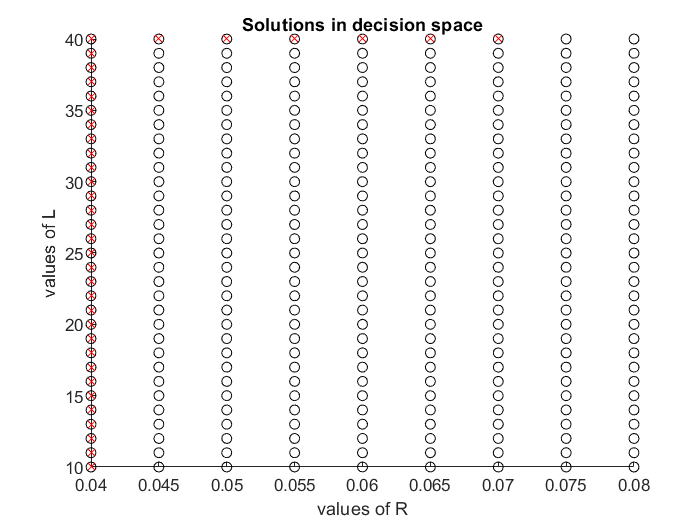

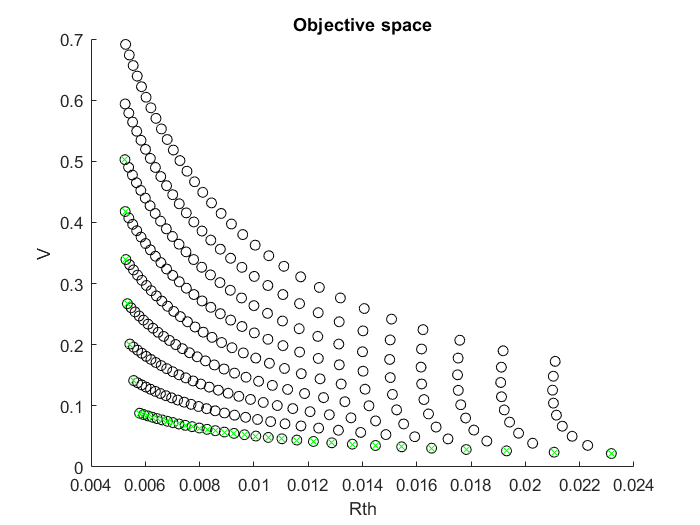

% lambda is with Rth, so 1-lambda for V
for lambda=0:0.005:1
% ws for weighted sum
ws=lambda.*Rthscale+(1-lambda).*Vscale;
% find them on decision space and solution space
[ilig icol]=find(ws==min(min(ws)));
% remind, ilig is for L, icol is for R
figure(1)
plot(R(icol),L(ilig),'rx')
figure(2)
plot(Rth(ilig,icol),V(ilig,icol),'gx')
end

## test